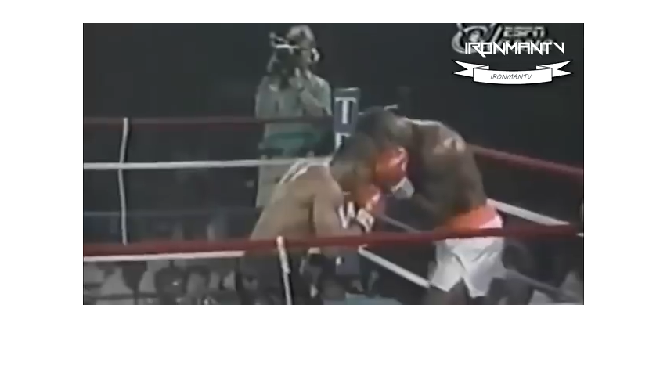

%% This script will be in charge of analyzing a video in real time
%% onto MATLAB and breaking it into frames 
%% Donavan Jeng



%read and upload video from folder
video = VideoReader("PunchNet/Video_Data/test_clip_MT.mp4")

video =   VideoReader with properties:

   General Properties:
            Name: 'test_clip_MT.mp4'
            Path: '/Users/donavanjeng/Documents/GitHub/PunchNet/Video_Data'
        Duration: 3.0933
     CurrentTime: 0
       NumFrames: 93
   Video Properties:
           Width: 640
          Height: 360
       FrameRate: 29.9700
    BitsPerPixel: 24
     VideoFormat: 'RGB24'

video.CurrentTime = 0; % start from 0 seconds of the video
numframes = video.numFrames

numframes = 93

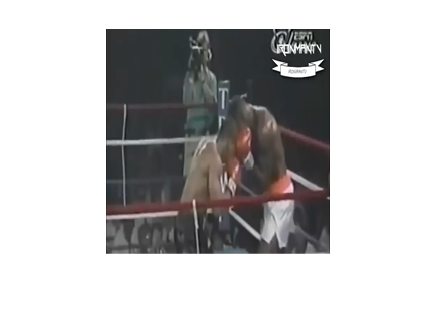

while hasFrame(video) %reads the video for how many frames it has. Will also simultaneously resize each frame
    vidFrame = readFrame(video); %reads frames 
    resizedFrame = imresize(vidFrame, [224,224]); 
    %set(x,'CData',vidFrame); %updates the image, more efficient way to display the frames
    imshow(resizedFrame);

end